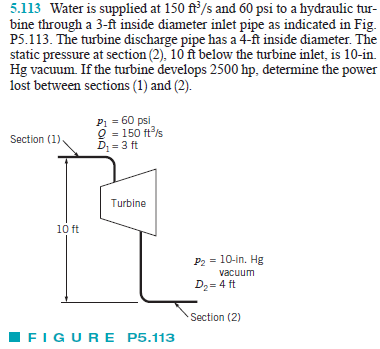

# given

u = symunit;
rho = 1.94*u.slug/u.ft^3;
gamma = 62.4*u.lbf/u.ft^3;
g = 32.2*u.ft/u.s^2;
Q = 150*u.ft^3/u.s;
Wdotshaft = -2500*u.HP_UK;

# inflow properties

p1 = 60*u.psi;
D1 = 3*u.ft;
A1 = sympi*D1^2/4;
V1 = Q/A1;
z1 = 10*u.ft;

# outflow properties

p2 = -sym(double(removeUnits(rewrite(10*u.inHg, u.psi))))*u.psi;
D2 = 4*u.ft;
A2 = sympi*D2^2/4;
V2 = Q/A2;
z2 = 0;

# conservation of energy

syms hL;
hs = rewrite(Wdotshaft/(gamma*Q), 'US');
hL = solve(p2/gamma+V2^2/(2*g)+z2 == p1/gamma+V1^2/(2*g)+z1+hs-hL);
hL = rewrite(hL, 'US');
Wdotloss = rewrite(hL*gamma*Q, u.HP_UK);
Wdotloss_vpa = vpa(Wdotloss, 5)

$$Wdotloss\_vpa = 300.78\,{\mathrm{HP}}_{\mathrm{UK}}$$